# Boundary Conditions: Dirichlet BC

clear all, close all, clc
set_defaults()

#### Problem statement

The for a crust with an exponential decay with heat production with depth, the geotherm solved the following Boundary Value Problem (BVP):

PDE: $-\nabla\cdot\left[\kappa \nabla T\right] = \rho H_0 e^{-z/h_r}$ on $z \in \left[0,\, h\right]$

BC's: $T(z=0) = 0\, ^{\circ}\mathrm{C}$ and $\left.\kappa \frac{\mathrm{d}T}{\mathrm{d}z}\right|_{z=h} = -q_m$

The analytic solution for the Temperature is given by

$T = T_0+\left(\frac{q_m}{\kappa}-\frac{\rho H_0h_r}{k}e^{-h/h_r}\right)z+\frac{\rho H_0 h_r^2}{k}(1-e^{-z/h_r})$.

This problem has both a Dirichlet and a Neumann BC!

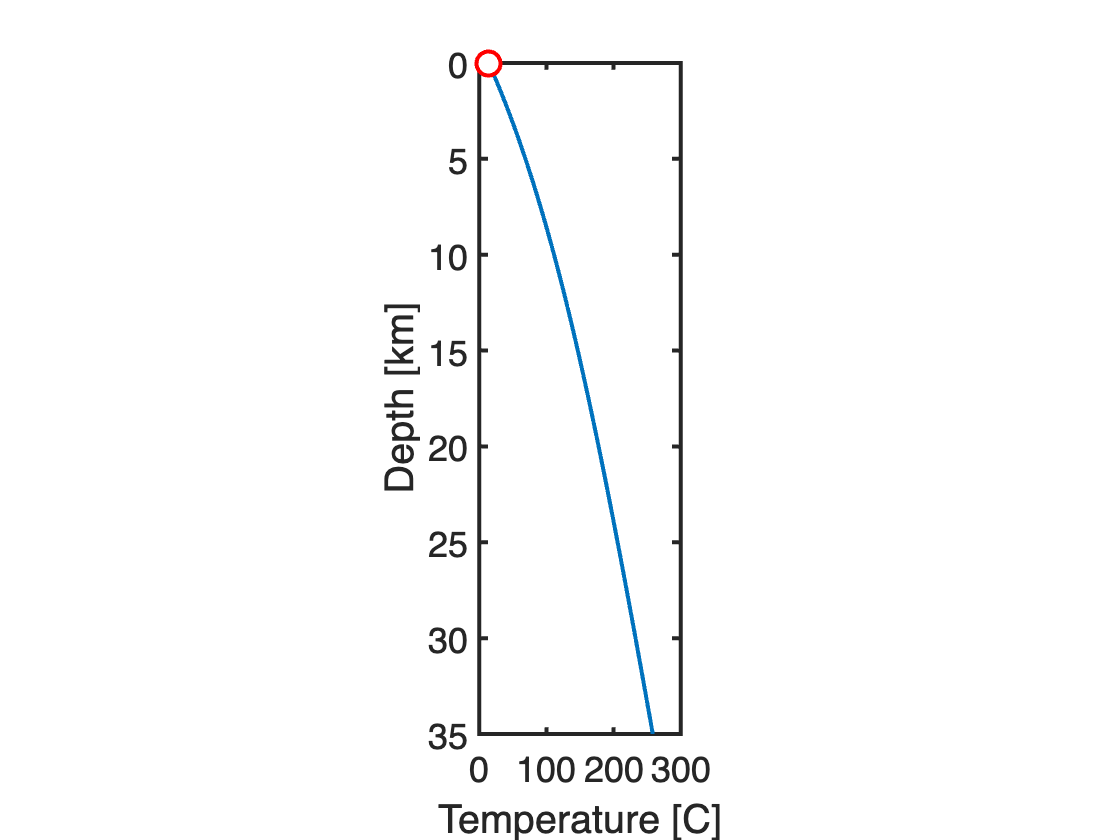

h = 35e3;     % ave. depth of crust [m]
hr = 10e3;    % decay depth [m]
H0 = 9.6e-10; % heat production near surface [W/kg]
rho = 2700;   % ave. crustal density [kg/m^3]
kappa = 3.35; % thermal conductivity [W/(m K)]
T0 = 14;      % surface temperature [C]
qm = 17e-3; % 

% Analtic solution for the temperature
zplot = linspace(0,h,100);
T = @(z) T0 + (qm/kappa-rho*H0*hr/kappa*exp(-h/hr))*z + rho*H0*hr^2/kappa*(1-exp(-z/hr));
figure
plot(T(zplot),zplot/1e3), hold on
plot([T0],[0]/1e3,'ro','markerfacecolor','w')
set(gca, 'YDir','reverse')
xlabel('Temperature [C]')
ylabel('Depth [km]')
pbaspect([.3 1 1])
xlim([0 300])

#### Simplified problem

First we need to learn how to impose the temperature at the surface, i.e., a Dirichlet BC. Therefore, we use the analytic solution to evaluate the temperature at the base of the crust and use it as a second boundary condition. With this simplification the problem becomes:

PDE: $-\nabla\cdot\left[\kappa \nabla T\right] =\rho H_0 e^{-z/h_r}$ on $x \in \left[0,\, h\right]$,

BC's: $T(z=0) = T_{0}$ and $T(z=h) = T_{b}$.

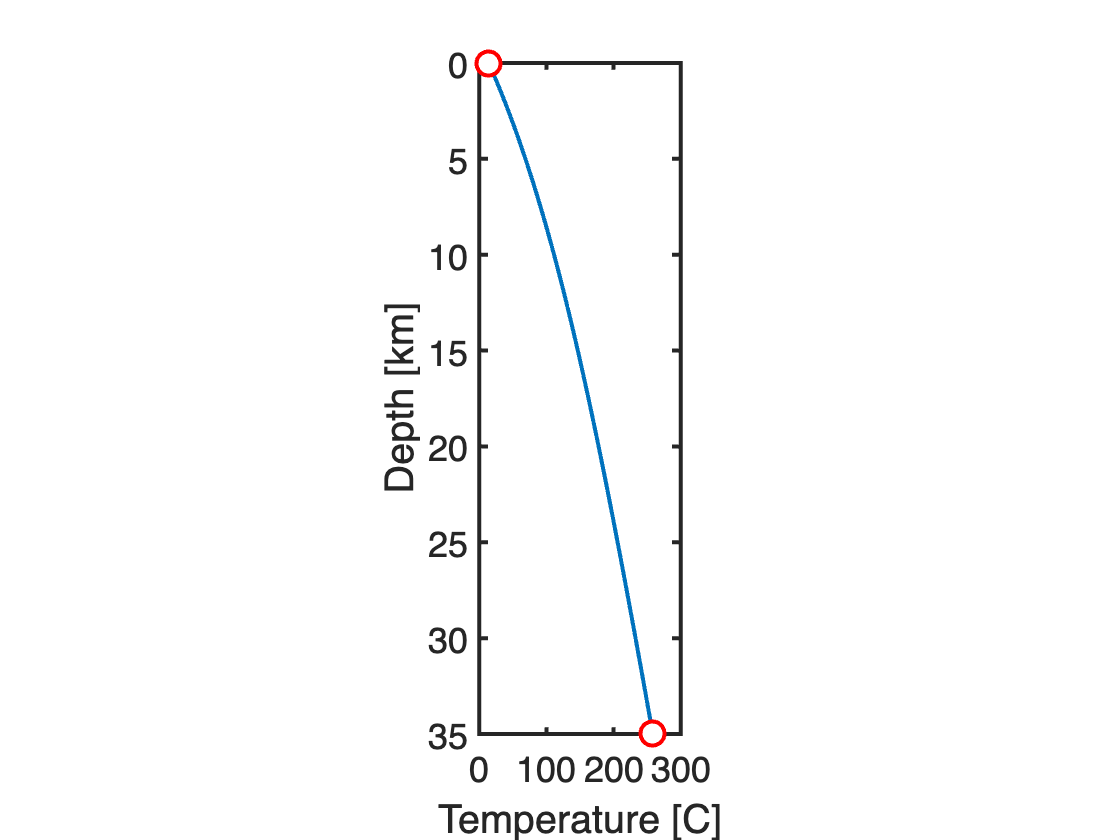

Tb = T(h);    % Basal temperature [C]
plot([Tb],[h]/1e3,'ro','markerfacecolor','w')

### Numerical solution

Using discrete operators the partial differential equation can be discretized as follows

`L``*``u ``=`` fs`

where `L = -D*Kd*G` is the discrete Laplacian operator, **u** is the unknown vector of temperatures and `fs` is the right hand side vector. Today we will discuss how to discretize the boundary condtions.

Without boundary conditions the problem is ill-posed and does not have a solution. This is reflected in the condition number of the discrete Laplacian operator, `L`.  Assume $H = 1$and $\kappa =1$for the purpose of demonstration.

Grid.xmin = 0; Grid.xmax = h; Grid.Nx = 20;
Grid = build_grid(Grid);
[D,G,~,I,M] = build_ops(Grid);
Kd = kappa*speye(Grid.Nf); % Conductivity matrix (more later)
L = -D*Kd*G; 
condest(L)

ans = Inf

A matrix with infinite condition number has no inverse. This is because there is an infinite number of possible solutions to the Laplace equation, only the boundary conditions (BC's) make the solution unique. 

#### Discretizing the boundary condition

Dirichlet BC's prescribe the solution on the boundary. In the discrete solution they prescribe the solution in the cells neighboring the boundaries. This constraint can be formulated as a linear system,

`B``*``u ``=`` g`

where `B` is the constrain matrix, `u` is the vector of unknowns (temperature), and **g** is a right hand side vector. The constrain matrix `B` is `Nc` by `Nx`, where `Nc` is the number of constraints, i.e., cells along Dirichlet boundaries with prescibed temperatures. This means that Dirichlet BC's provide constraints that reduce the overall number of unknown we need to solve for.

Therefore the boundary value problem is described by two linear systems

1) `L``*``u`` = ``fs`, arising from the PDE, where `L` is the `Nx` by `Nx` ***system matrix***

2) `B``*``u`` = ``g`, arising from the BC's, where **B** is the `Nc` by `Nx` ***constraint matrix***

Neither **L** nor **B** is invertible, both allow infinite solutions. To find the unique solution to the boundary value problem, the constraints in `B` must be eliminated from the system matrix `L`.

$\Rightarrow$**we need to understand how to eliminate constraints**

## Building the constraint matrix

Suppose we have the following two Nc by 1 column vectors:

- `dof_dir`: contains the degrees of fredom (dofs), i.e., cell numbers, of all cells along the Dirichlet boundary.

- `g`: contains the prescribed values the unknown is set to along the Dirichlet boundary.

The constraint matrix, **B**, needs to set the unknown in `dof_dir` to `g`. The matrix B therefore comprises the rows of the Nx by Nx identity matrix, `I`, that correspond to `dof_dir`. Therefore `B` can be built as follows

dof_dir = [Grid.dof_xmin;Grid.dof_xmax];
B = I(dof_dir,:);
figure
size(B)

ans =      2    20


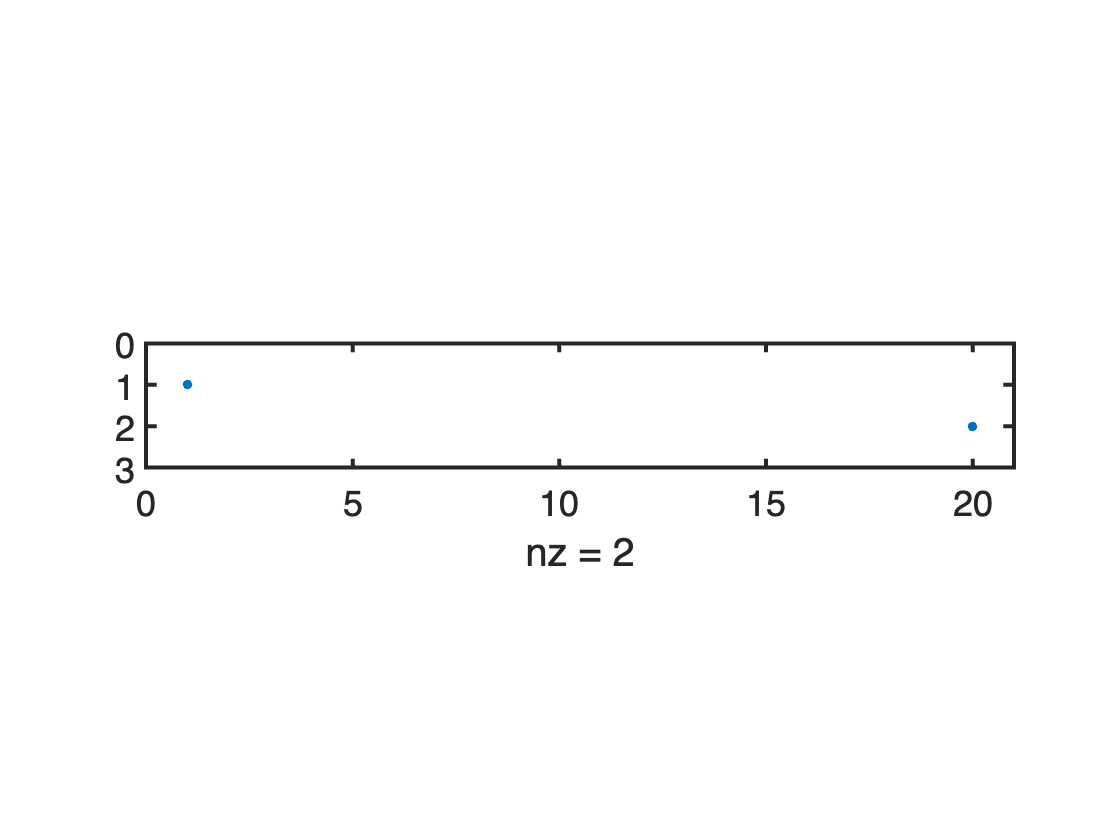

spy(B)

The resulting constraint matrix has one row for every cell that is set to a prescribed value by the Dirichlet BC's. In the 1D case with Diriclet BC's at both ends `Nc = 1` and `B` only has 2 rows. This simple construction will remain the same, even in higher dimensions.

# Homogeneous constraints

However, before we can walk we need to learn how to crawl. Initially, we consider a problem with homogeneous constraints, i.e., $T(z=0) = T(z=H)=0$. To have a non-trivial solution, i.e., $T(z) \neq 0$, with these boundary conditions we need a finite source term, $f_s\neq0$. Let's consider the following test problem

PDE: $-\nabla\cdot\left[\kappa \nabla T\right] =\rho H_0 e^{-z/h_r}$ on $x \in \left[0,\, h\right]$,

BC's: $T(z=0) = T(Z=h) = 0$

with the analytic solution 

$T = \frac{\rho H_0h_r^2}{\kappa}\left[\left(1-e^{\frac{z}{h_r}}\right)+ \left(1-e^{\frac{h}{h_r}}\right)\frac{z}{h}\right]$.

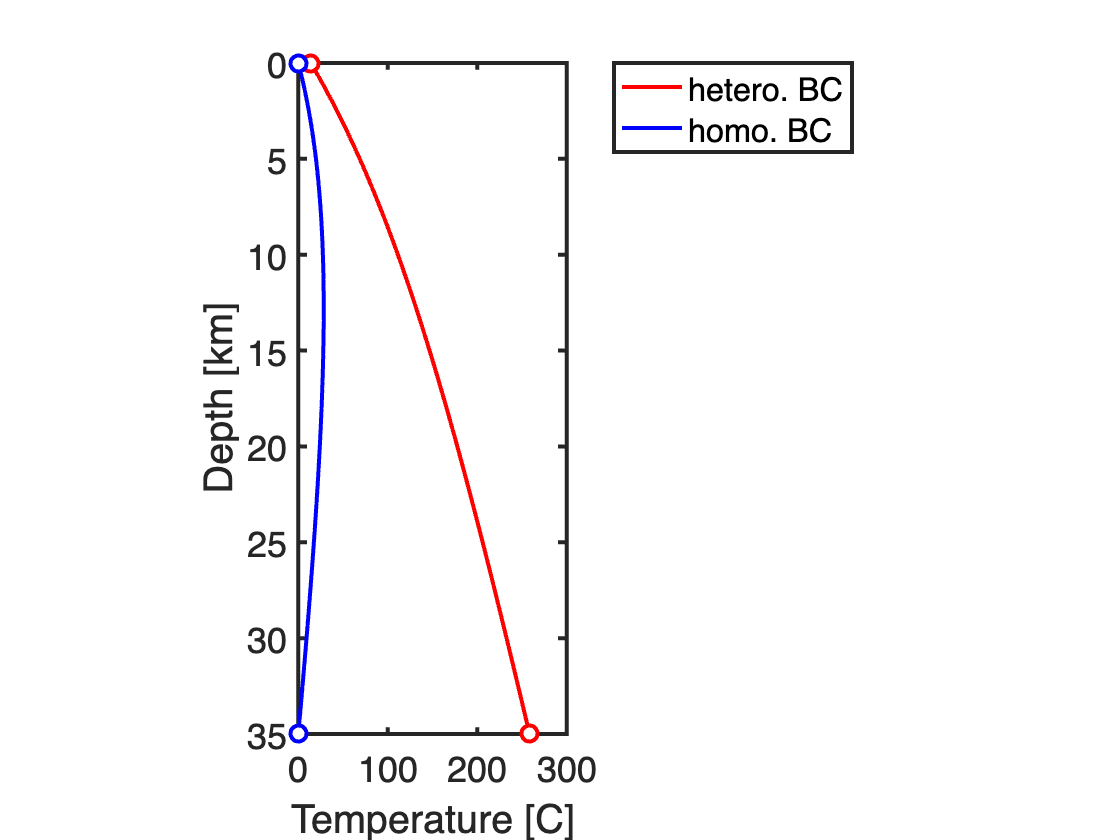

% Analytic solution for homogeneous BC's
x_ana = linspace(Grid.xmin,Grid.xmax,1e2);
u_ana = @(z) rho*H0*hr^2/kappa*(1-exp(-z./hr))-rho*H0*hr^2/kappa*(1-exp(-h/hr)).*z/h;


figure
plot(T(x_ana),x_ana/1e3,'r'), hold on
plot(u_ana(x_ana),x_ana/1e3,'b')
plot(T([0 h]),[0 h]/1e3,'ro','markerfacecolor','w','markersize',8)
plot(u_ana([0 h]),[0 h]/1e3,'bo','markerfacecolor','w','markersize',8)
set(gca, 'YDir','reverse')
xlabel('Temperature [C]')
ylabel('Depth [km]')
pbaspect([.4 1 1])
xlim([0 300])
legend('hetero. BC','homo. BC','Location','northeastoutside')

The discrete problem is then given by

PDE: `L``*``u`` = ``fs`

BC's: `B``*``u`` = ``0`

## **Reduced linear system**

Given that the constraints in `B` reduce the number of unknown we expect to solve a smaller or reduced linear system of size `(Nx-Nc)` by `(Nx-Nc)`

`Lr``*``ur ``=`` fsr.`

Here the variables are:

- `ur` is the (Nx-Nc) by 1 reduced vector of unknows.

- `fsr` is the (Nx-Nc) by 1 reduced r.h.s. vector.

- `Lr` is the (Nx-Nc) by (Nx-Nc) reduced system matrix.

## Projection matrix

What is the relation between `u` and `ur`, `fs` and `fsr`, and `L` and `Lr`? Two vectors of different length are related by a rectangular matrix

`u`` = ``N``*``ur` and `fs`` = ``N``*``fsr`

where `N` is a Nx by (Nx-Nc) matrix. Here **N** is any basis for the [nullspace](https://ocw.mit.edu/courses/mathematics/18-06-linear-algebra-spring-2010/video-lectures/lecture-6-column-space-and-nullspace/) of the constraint matrix **B**. The nullspace of **B** is simply the set of all solutions that satisfy `B``*``u`` = ``0`, i.e., all the possible solutions that satisfy the homogeneous boundary conditions.  If we search for solutions to `L``*``u``=``fs` in the nullspace of **B**, then the BC's are automatically satisfied. In Matlab the nullspace of a matrix can be found with the function [null()](https://www.mathworks.com/help/matlab/ref/null.html) or [spnull()](https://www.mathworks.com/matlabcentral/fileexchange/27550-sparse-null-space-and-orthogonal?focused=5152745&tab=function) for sparse matrices.

N = spnull(B);
size(N)

ans =     20    18


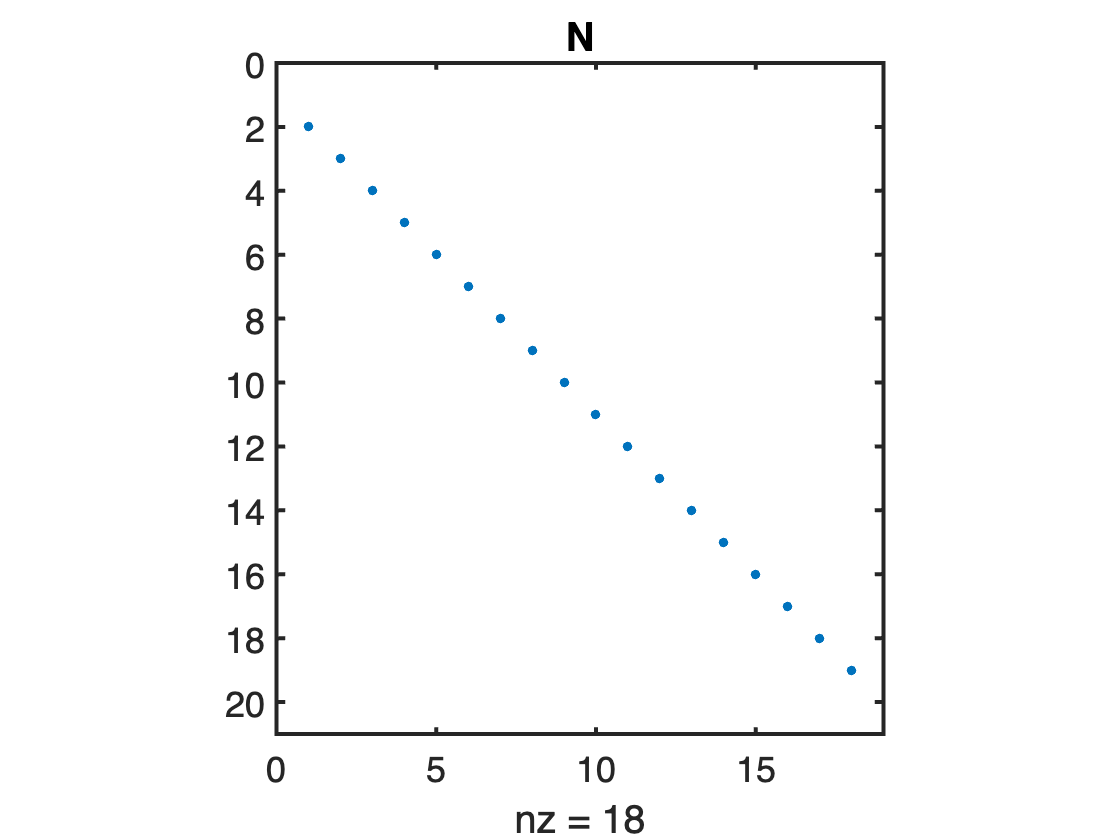

figure
spy(N), title 'N'

Assume that `N` is orthonormal, i.e., that the dot product between all columns is unity. the it follows that

- `N'``*``N`` = ``Ir`, where `Ir` is the `(Nx-Nc)` by `(Nx-Nc)` identity matrix in the reduced space.

- **N*****N'** = **Ic**, where Ic is the `Nx` by `Nx` "identity matrix" with `Nc` zeros on the diagonal.

Ir = N'*N;
size(Ir)

ans =     18    18


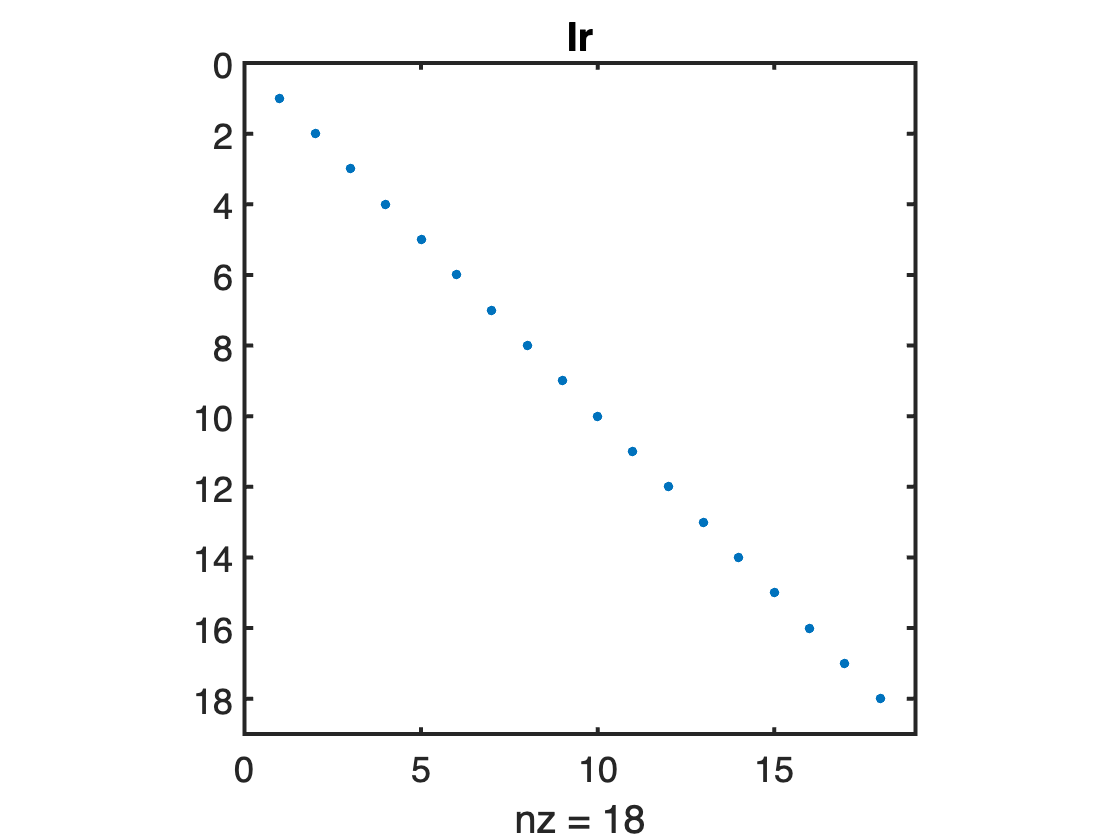

spy(Ir), title 'Ir'

non_0_entries_Ir = full(sum(diag(Ir)))

non_0_entries_Ir = 18


Ic = N*N';
size(Ic)

ans =     20    20


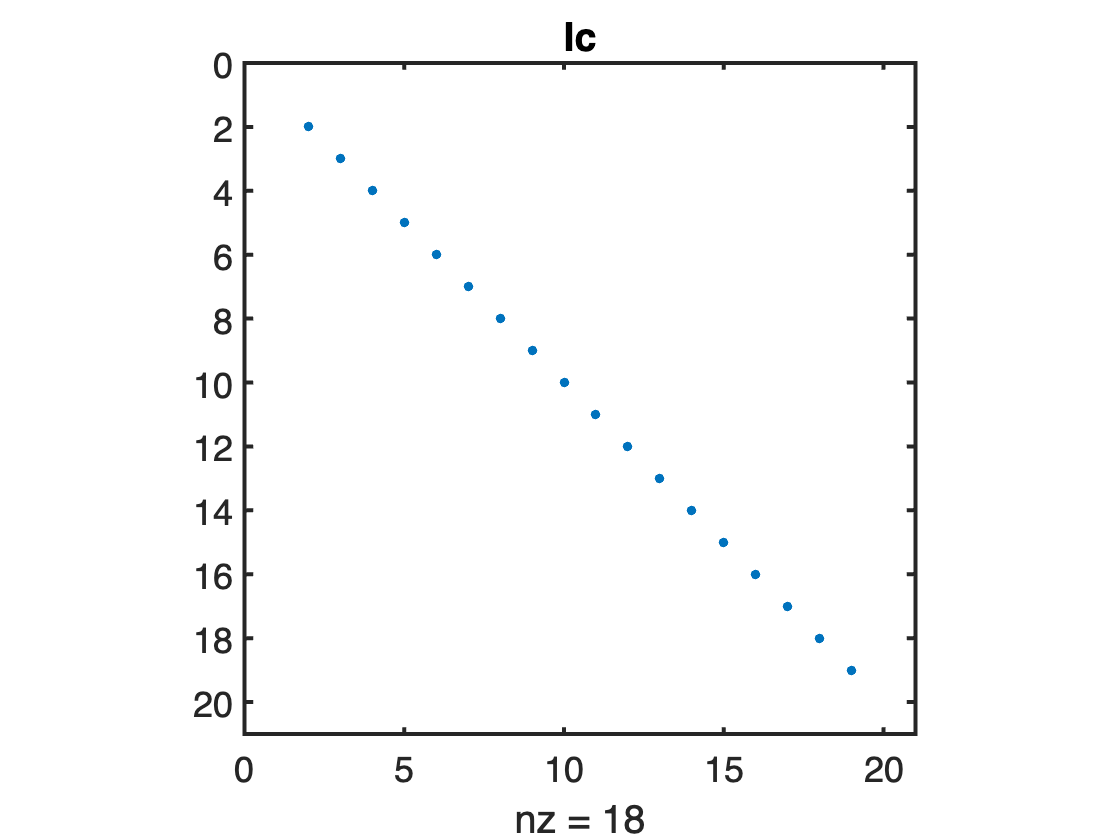

spy(Ic), title 'Ic'

non_0_entries_Ic = full(sum(diag(Ic)))

non_0_entries_Ic = 18

In this case, we have the following relationship, `N``'*``u`` = ``N``'*``N``*``ur`` = ``Ir``*``ur`` = ``ur`, so that `N` and `N`' allow us to go forth and back between `u` and `ur`:

`u`` = ``N``*``ur`

`ur`` = ``N``'*``u`

Of course, the same relationship exists between `fsr`` and ``fs, fsr ``=`` N``'*``fs`.

The matrix `N``'` *projects* the vector of unknowns into the nullspace of `B`. Note that a proper [projection matrix](https://ocw.mit.edu/courses/mathematics/18-06-linear-algebra-spring-2010/video-lectures/lecture-16-projection-matrices-and-least-squares/) is square, it would simply zero our the entries that are not in the nullspace. Instead, our `N``'` matrix eliminates these entries, but the idea is the same. 

## Reduced system matrix

Given the properties of N, defined above, the expression for the reduced system matrix is derived as follows

`L``*``u`` = ``fs`

`N``'*``L``*``u`` = ``N``'*``fs`

`N``'*``L``*``Ic``*``u`` = ``N``'*``fs`

`N``'*``L``*(``N``*`**N')**`*``u`` = ``N``'*``fs`

`(N``'*``L``*``N``)*(`**N'**`*``u)`` = ``N``'*``fs`

`Lr``*``ur`` = ``fsr`

where 

- `Lr`` = ``N``'*``L``*``N`

- `ur ``=`` N'``*``u`

- `fsr ``=`` N'``*``fs`

Lr = N'*L*N;
size(Lr)

ans =     18    18


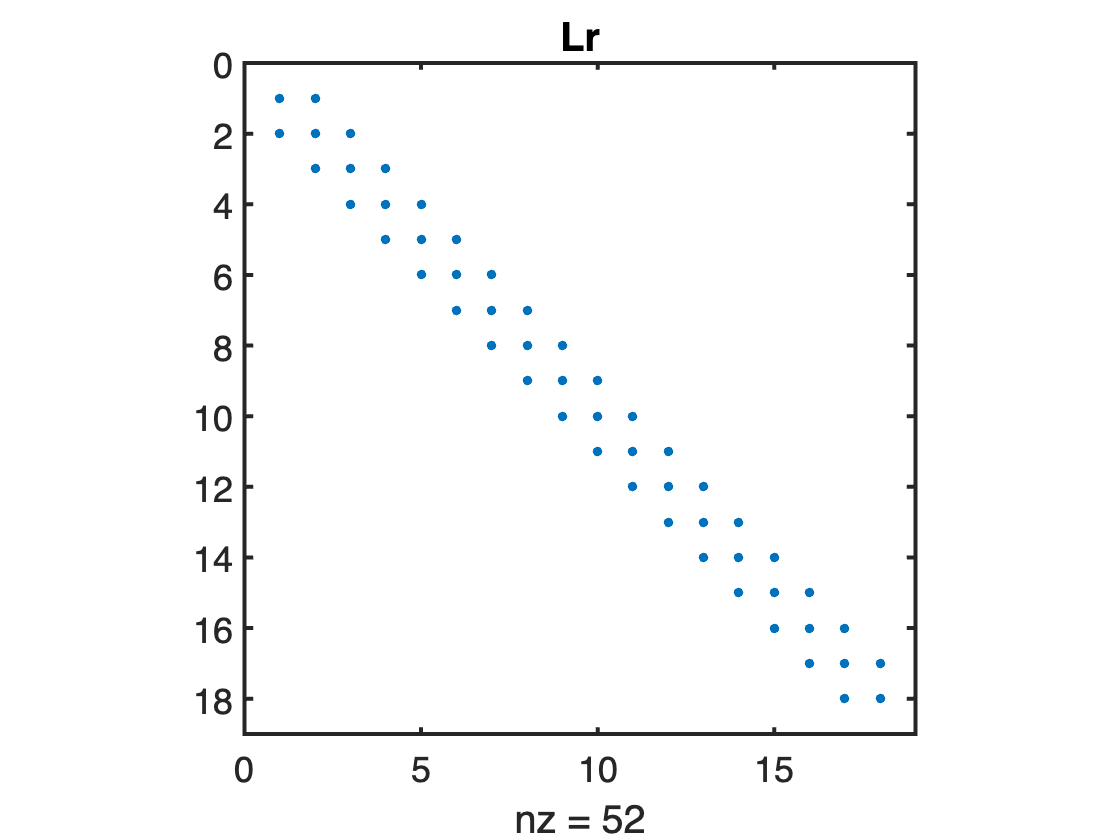

spy(Lr), title 'Lr'

The reduced system matrix Lr is not singular anymore, because the constraints have been incorporated. This can be checked by estimating the condition number

condest(Lr)

ans = 180

## Solving problem with homogeneous boundary conditions

Solving a steady problem with homogeneous boundary conditions therefore requires 3 steps:

- Compute `N` and obtain `Lr` and `fsr`.

- Solve reduced problem: `ur`` = ``Lr``\``fsr`.

- Obtain full solution: `u`` = ``N``*``ur`.

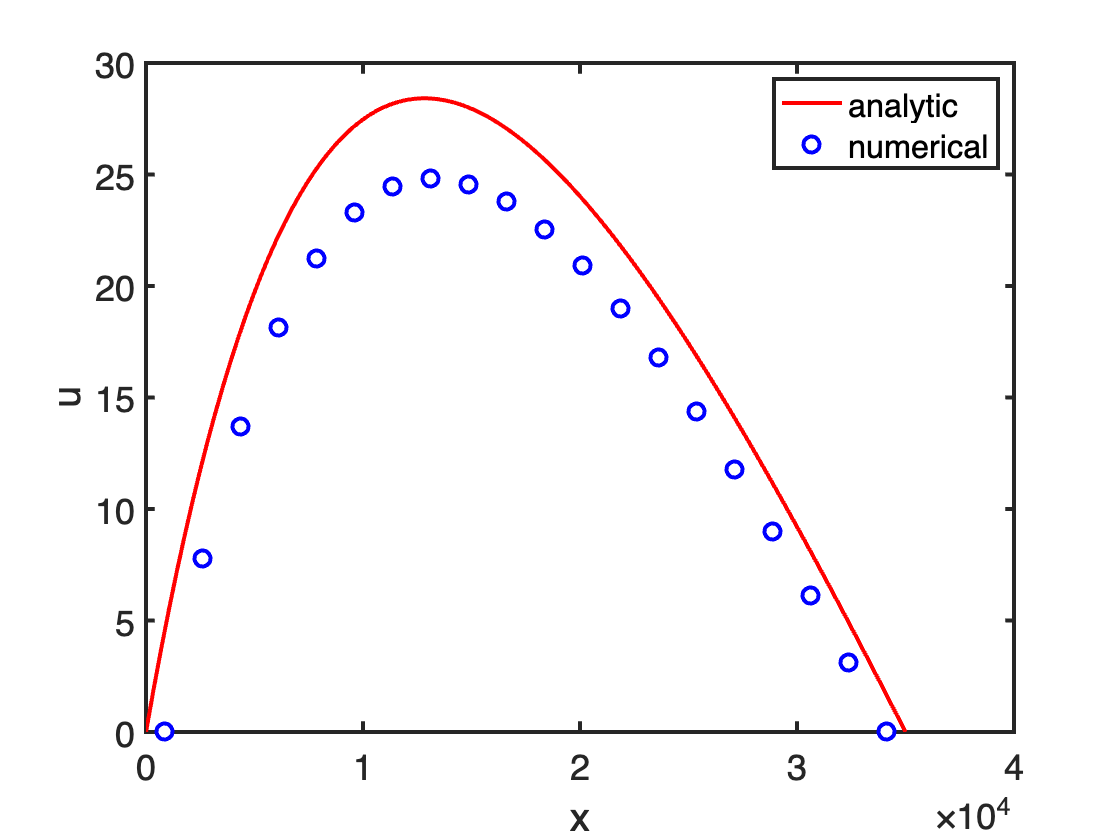

fs = rho*H0*exp(-Grid.xc/hr);
fsr = N'*fs;
ur = Lr\fsr;
u = N*ur;
u = u; 
plot(x_ana,u_ana(x_ana),'r-',Grid.xc,u,'bo','MarkerFaceColor','w','markersize',8)
xlabel 'x', ylabel 'u'
legend('analytic','numerical')

Note, the boundary condition is set at the center of the first cell, which makes the solution look bad (first order error).

If we shift the solution upward by the appropriate amount the fit to the analytic solution is quite good.

# Heterogeneous constraints

We are interested in solving for the geotherm which requires heterogeneous, i.e., non-zero, BC's. In this case

 `B``*``u`` = ``g`,

where `g`` = [T0;Tb]` is a vector containing the two boundary conditions.

% clear Grid L B N 
% Grid.xmin = 0; Grid.xmax = 3.5e4; Grid.Nx = 20;
% Grid = build_grid(Grid);
% [D,G,~,I,M] = build_ops(Grid);
% Kd = kappa*speye(Grid.Nf);
% L = -D*Kd*G; fs = rho*H0*exp(-Grid.xc/hr);

To obtain the solution of a problem with heterogeneous boundary conditions, we split the solution into a homogeneous and a particular solution as follows

`u`` = ``u0`` + ``up`,

where the homogeneous solution solves `B``*``u0`` = ``0` as before and the particular solution solves `B``*``up`` = ``g`. The solution then proceeds in three steps

- Find a particular solution that satisfies `B``*``up`` = ``g`.

- Find the associated homogeneous solution, `u0`.

- Find total solution `u`` = ``u0`` + ``up`.

## Find a particular solution

Note there are many possible particular solutions, here we just find the simplest one. Also not that `up` does not need to satisfy `L``*``up ``=`` fs` it only needs to satisfy the boundary conditions `B``*``up ``=`` g`. Since the system is not square and `Nx > Nc` and `B` has only `Nc` entries we can again project into a reduced space of size `Nc`. 

It is natural to use `B` as projection matrix, so that `upr`` = ``B``*``up` and `up`` = ``B'``*``upr`. We derive the reduced system as follows

`B``*``up`` = ``g`

`B``*(``B'``*``upr``) = ``g`

`(``B``*``B'``)*``upr`` = ``g`

`Br``*``upr ``=`` g`

where the reduced constraint matrix is `Br`` = ``B``*``B'` is `Nc` by `Nc`. For the simple constraints we use here `Br` is simply the `Nc` by `Nc` identity matrix, so that `upr`` = ``g`.  However, our definition is also valid for more general constraints so we'll stick with that. Once `upr` is known the full particular solution can be recovered, `up`` = ``B'``*``upr`.

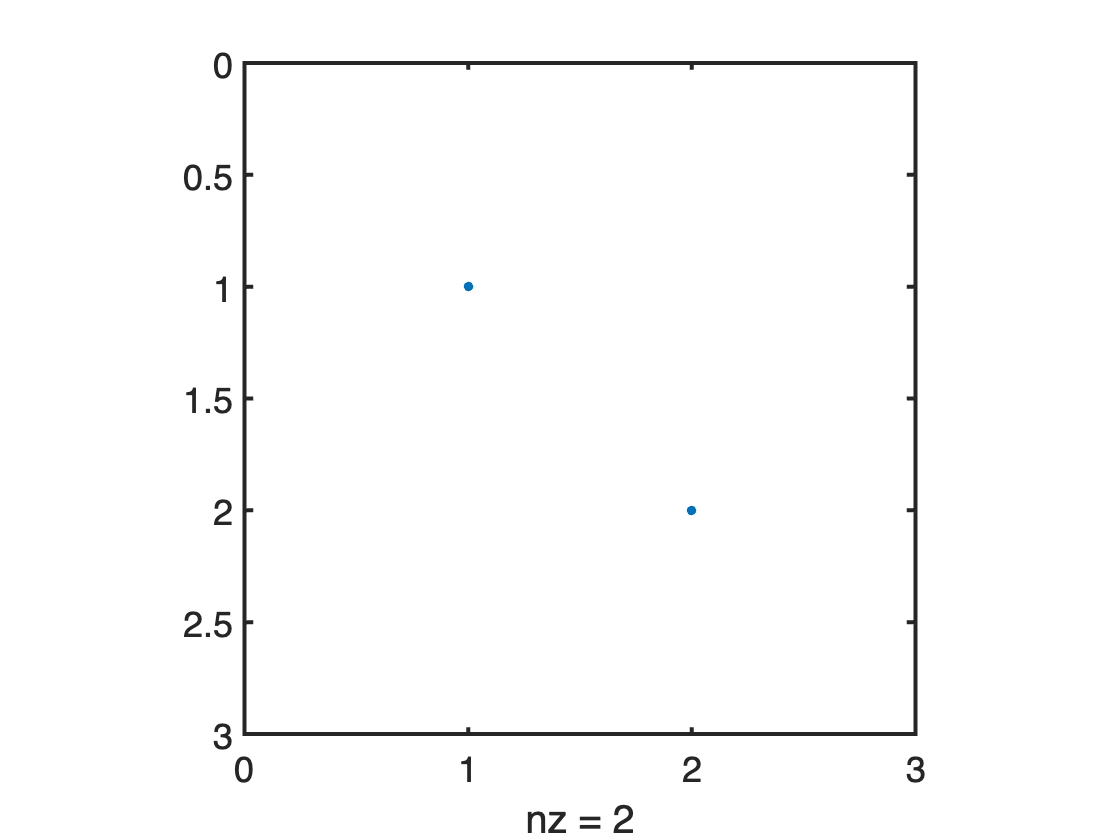

g = [T0;Tb];
g = [T(Grid.xc(dof_dir))];

dof_dir = [Grid.dof_xmin;Grid.dof_xmax];
B = I(dof_dir,:);
Br = B*B';
spy(Br)

upr = Br\g;
up = B'*upr;

## Find associated homogeneous solution

Once up is known we find the associated homogeneous solution, h0, as follows

`L``*``u`` = ``fs`

`L``*(``u0``+``up``) = ``fs`

`L``*``u0 ``=`` fs ``-`` L``*``up`

`L``*``u0 ``=`` fs + fd`

where `fd = -L``*``up `is a new source term due to heterogeneous Dirichlet BC's. But the problem can be solved with the nullspace projection for homogeneous problems as above. Combining the r.h.s. f = fs + fd we solve as follows

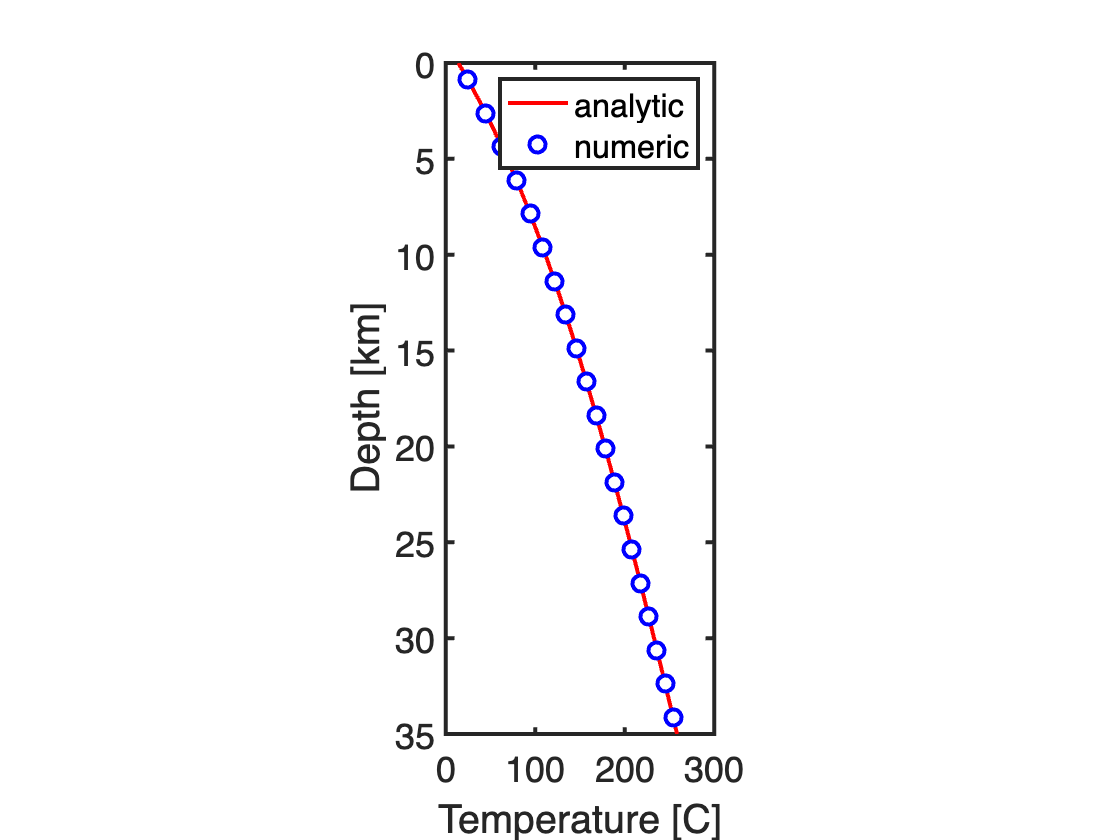

N = I; N(:,dof_dir)=[]; % simple/fast way to generate N without spnull()
fd = -L*up;
f = fs + fd;
% Reduced system
fr = N'*f;
Lr = N'*L*N;
u0r = Lr\fr;
u0 = N*u0r;

% Total solution
u = u0 + up;

figure
plot(T(x_ana),x_ana/1e3,'r'), hold on
plot(u,Grid.xc/1e3,'bo','markerfacecolor','w','markersize',8)
set(gca, 'YDir','reverse')
xlabel('Temperature [C]')
ylabel('Depth [km]')
pbaspect([.4 1 1])
xlim([0 300])
legend('analytic','numeric')

# Auxillary functions

This implementation of spnull() is taken from [Bruno Luong](https://www.mathworks.com/matlabcentral/profile/authors/390839-bruno-luong), thanks man!

function Z = spnull(S, varargin)
% Z = SPNULL(S)
% returns a sparse orthonormal basis for the null space of S, that is,
% S*Z has negligible elements, and Z'*Z = I
%
% If S is sparse, Z is obtained from the QR decomposition.
% Otherwise, Z is obtained from the SVD decomposition
%
% Bruno Luong <brunoluong@yahoo.com>
% History
%   10-May-2010: original version
%
% See also SPORTH, NULL, QR, SVD, ORTH, RANK

if issparse(S)
    [m n] = size(S);
    try
        [Q R E] = qr(S.'); %#ok %full QR
        if m > 1
            s = diag(R);
        elseif m == 1
            s = R(1);
        else
            s = 0;
        end
        s = abs(s);
        tol = norm(S,'fro') * eps(class(S));
        r = sum(s > tol);
        Z = Q(:,r+1:n);
    catch %#ok
        % sparse QR is not available on old Matlab versions
        err = lasterror(); %#ok
        if strcmp(err.identifier, 'MATLAB:maxlhs')
            Z = null(full(S), varargin{:});
        else
            rethrow(err);
        end
    end
else % Full matrix
    Z = null(S, varargin{:});
end

end

## set_defaults()

function [] = set_defaults()
    set(0, ...
    'defaultaxesfontsize',   18, ...
    'defaultaxeslinewidth',   2.0, ...
    'defaultlinelinewidth',   2.0, ...
    'defaultpatchlinewidth',  2.0,...
    'DefaultLineMarkerSize', 12.0);
end